## Problemas de valores iniciais no MATLAB

Funções do MATLAB (*solvers*) mais usadas para resolver PVI: [**ode45**](https://www.mathworks.com/help/matlab/ref/ode45.html)**, **[**ode23**](https://www.mathworks.com/help/matlab/ref/ode23.html)

**Sintaxe:**

- *[t,y] = solver(funcao,intervalo,y0)*

- *sol = solver(funcao,intervalo,y0...)*

- *[t,y] = solver(funcao,intervalo,y0,opcoes)*

usa as configurações definidas pela função [**odeset**](https://www.mathworks.com/help/matlab/ref/odeset.html?searchHighlight=odeset&s_tid=srchtitle_odeset_1).

- *[t,y,te,ye,ie] = solver(funcao,intervalo,y0,opcoes)*

 O output inclui ainda descrição de um determinado evento 

especificado pela função [**odeset**](https://www.mathworks.com/help/matlab/ref/odeset.html?searchHighlight=odeset&s_tid=srchtitle_odeset_1):

 *te* - hora do evento, *ye* - solução na hora do evento e *ie* - índice do evento .

#### Exemplo: 

Considere o PVI $y'=x y^2$, $y(0)=1$, cuja solução exata é $\frac1{1 + x^2}$ .

1) Represente graficamente a solução em [0,1]

2) Avalie a solução nos pontos 0:0.2:1

3) Estime o erro em x=1.

4) Repita o exercício, usando na função odeset os parâmetros: 

RelTol=1e-8, AbsTol=1e-9, OutputFcn=@odeplot e Stats='on'.

5) Crie um evento que permita obter o valor de x para o qual y=0.75.

f=@(x,y)-2*x.*y.^2; 
exata=@(x) 1./(1+x.^2);

1) Primeira solução:

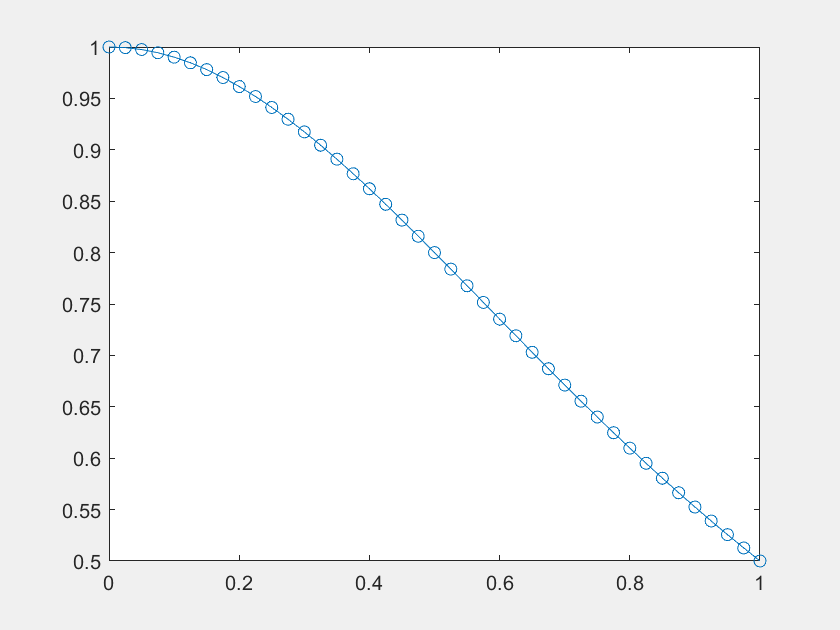

ode45(f,[0,1],1)

[x,y]=ode45(f,[0,1],1)

x =          0
    0.0250
    0.0500
    0.0750
    0.1000
    0.1250
    0.1500
    0.1750
    0.2000
    0.2250


y =     1.0000
    0.9994
    0.9975
    0.9944
    0.9901
    0.9846
    0.9780
    0.9703
    0.9615
    0.9518


y

y =     1.0000
    0.9994
    0.9975
    0.9944
    0.9901
    0.9846
    0.9780
    0.9703
    0.9615
    0.9518


xout=0:0.2:1;  
[x,y]=ode45(f,xout,1)

x =          0
    0.2000
    0.4000
    0.6000
    0.8000
    1.0000


y =     1.0000
    0.9615
    0.8621
    0.7353
    0.6098
    0.5000


sol=ode45(f,[0,1],1)

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
          y: [1 0.9901 0.9615 0.9174 0.8621 0.8000 0.7353 0.6711 0.6098 0.5525 0.5000]
      stats: [1×1 struct]
      idata: [1×1 struct]


sol.solver

ans = 'ode45'

sol.x

ans =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


sol.y

ans =     1.0000    0.9901    0.9615    0.9174    0.8621    0.8000    0.7353    0.6711    0.6098    0.5525    0.5000


sol.stats

ans = struct with fields:
     nsteps: 10
    nfailed: 0
    nfevals: 61
     tfinal: 1


deval(sol,0.97)

ans = 0.5152

erro=abs(sol.y-exata(sol.x))

erro = 1.0e-08 *

         0    0.0381    0.0041    0.0876    0.2065    0.3216    0.3795    0.3223    0.1329    0.1528    0.4712


2) Segunda solução:

opcoes=odeset('AbsTol',1e-12,'RelTol',1e-8,'OutputFcn',@odeplot,'Stats','on');
[x y]=ode45(f,[0,1],1,opcoes)

erro=abs(y(end)-exata(1))

## Eventos:

A função eventos deverá ser da forma geral

`        [valor,termina,direcao] = eventos(x,y),`

`por exemplo (conteúdo do ficheiro myeventos.m):`

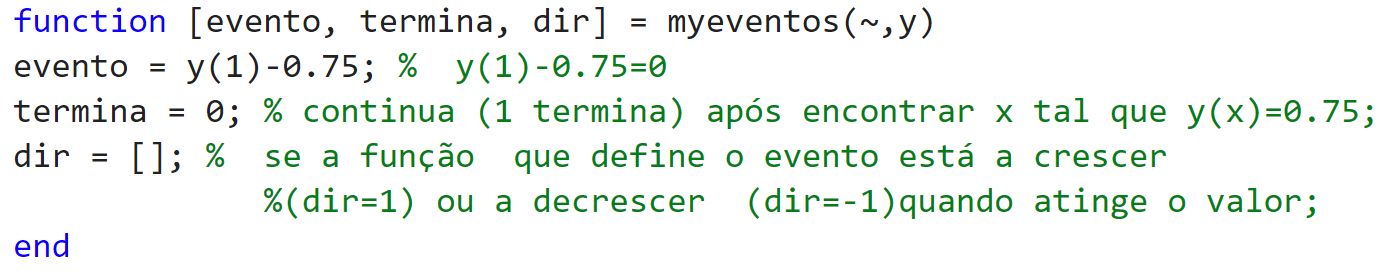

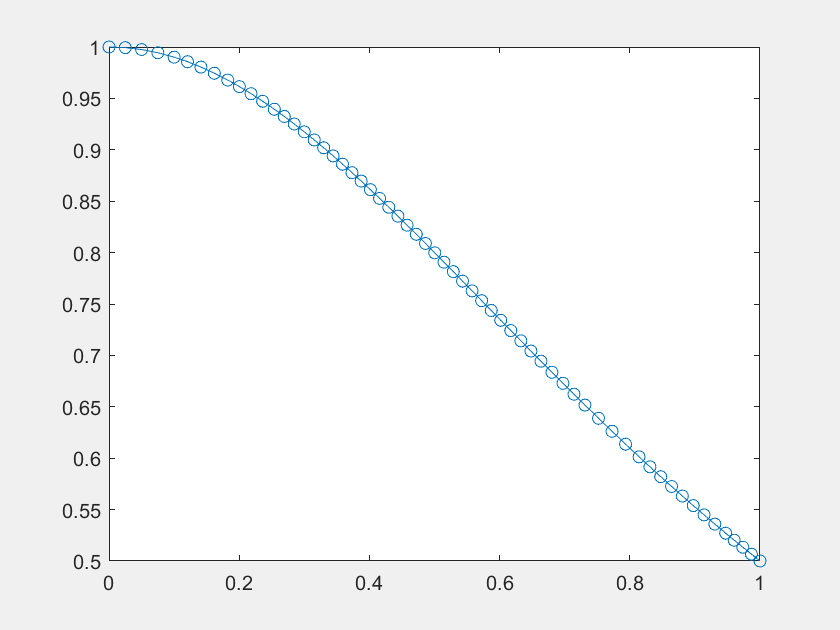

15 successful steps
1 failed attempts
97 function evaluations


x =          0
    0.0250
    0.0500
    0.0750
    0.1000
    0.1206
    0.1412
    0.1618
    0.1823
    0.2002


y =     1.0000
    0.9994
    0.9975
    0.9944
    0.9901
    0.9857
    0.9805
    0.9745
    0.9678
    0.9615


opcoes=odeset('Events',@myeventos,'OutputFcn',@odeplot);

[x,y,tempo_Evento] =ode45(f,[0,1],1,opcoes);

erro = 8.3749e-10

tempo_Evento = 0.5774

tempo_Evento